First we must load the zip where the entire data set of the characters is located to carry out their categorization by classes.

In the same way, the image must be loaded to make the comparison.

unzip("/Users/fcuervo/MATLAB-Drive/VisionArtificial/Characters.zip")
%IG = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/PreprocessedImages/PreprocessedImage4.png")
%Image = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090831011.jpg");
% Load image
Image = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/PreprocessedImages/PrepocessedFinal2.jpg");

% Take the folder with all the character dataset and create a datastore to manipulate our data.
imds = imageDatastore('Characters','IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.37.png';
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.47.png';
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.57.png'
                               ... and 175 more
                              }
                     Folders: {
                              '/Users/fcuervo/MATLAB-Drive/VisionArtificial/Characters'
                              }
                      Labels: [0; 0; 0 ... and 175 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


% Review the number of images per category (folders)
tbl = countEachLabel(imds)

tbl = 36×2 table
    Label    Count
    _____    _____

      0        5  
      1        4  
      2        4  
      3        4  
      4        5  
      5        5  
      6        5  
      7        5  
      8        5  
      9        5  
      A        5  
      B        5  
      C        5  
      D        5  
      E        5  
      F        5  


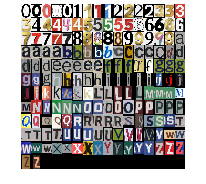


% Display some images of your dataset
figure
montage(imds.Files(1:1:end))

% 30% of from each set is for training data, and 40% for the validation
% data, apply randomize to avoid biasing the results.
[trainingSet, validationSet] = splitEachLabel(imds, 0.3, 'randomize')

trainingSet =   ImageDatastore with properties:

                       Files: {
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.06.04.png';
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.06.21.png';
                              ' .../Characters/1/Captura de Pantalla 2022-10-12 a la(s) 16.07.35.png'
                               ... and 66 more
                              }
                     Folders: {
                              '/Users/fcuervo/MATLAB-Drive/VisionArtificial/Characters'
                              }
                      Labels: [0; 0; 1 ... and 66 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastore

validationSet =   ImageDatastore with properties:

                       Files: {
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.37.png';
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.47.png';
                              ' .../Characters/0/Captura de Pantalla 2022-10-12 a la(s) 16.05.57.png'
                               ... and 106 more
                              }
                     Folders: {
                              '/Users/fcuervo/MATLAB-Drive/VisionArtificial/Characters'
                              }
                      Labels: [0; 0; 0 ... and 106 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas

Create your visual vocabulary. This method extracts SURF features from all images in all the categories. This will construct the visual vocabulary by reducing the number of features through quantization of feature space using K-means clustering.

bag = bagOfFeatures(trainingSet)

Creating Bag-Of-Features.
-------------------------
* Image category 1: 0
* Image category 2: 1
* Image category 3: 2
* Image category 4: 3
* Image category 5: 4
* Image category 6: 5
* Image category 7: 6
* Image category 8: 7
* Image category 9: 8
* Image category 10: 9
* Image category 11: A
* Image category 12: B
* Image category 13: C
* Image category 14: D
* Image category 15: E
* Image category 16: F
* Image category 17: G
* Image category 18: H
* Image category 19: I
* Image category 20: J
* Image category 21: K
* Image category 22: L
* Image category 23: M
* Image category 24: N
* Image category 25: O
* Image category 26: P
* Image category 27: Q
* Image category 28: R
* Image category 29: S
* Image category 30: T
* Image category 31: U
* Image category 32: V
* Image category 33: W
* Image category 34: X
* Image category 35: Y
* Image category 36: Z
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.


bag =   bagOfFeatures with properties:

       NumVisualWords: 500
       TreeProperties: [1 500]
    StrongestFeatures: 0.8000
       PointSelection: 'Grid'
             GridStep: [8 8]
           BlockWidth: [32 64 96 128]
              Upright: 1


% Count the visual word occurences in an image 
img = readimage(imds, 1)

img = 490×360×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   254   255   255   255   255   254   239   239   238   239   239   238   240   239   239   239   239   239   239   238   239   239   239   239   240   239   239   239   255   255   255   255   254   255   255   255   255   254   255   255   254   255   255   254   255   255   255   255   239   239   239   238   239   239   239   239   240   239   239   239   239   239   239   239   238   239   239   238   240   238   255   255   254   255   255   254   255   255   255   255   255   255   255   254   255   255   255   255   255   255   239   239   239   239   239   239   238   239   239   238   240   238   239   239   238   239   239   238   240   239   235   204   173   104    33     0     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1    

featureVector = encode(bag, img)

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


featureVector = 1×500 single row vector
    0.0145    0.0145    0.0013    0.0020    0.0020    0.0937    0.0046    0.0257    0.0007    0.0112    0.0007    0.0990         0    0.0040    0.0304    0.0079    0.0020    0.0007    0.0310    0.0020         0    0.0766    0.0007    0.0555         0    0.0112    0.0033    0.0139    0.1248    0.0198    0.0119    0.0158         0    0.0013         0         0    0.0251    0.0026    0.0013    0.0053    0.0013    0.0033    0.0660    0.0323    0.0040    0.0119    0.0370    0.0033    0.0746         0


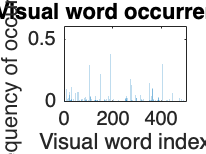


% Plot histograms of visual word occurences. Histograms fornm a basis for
% training a cllassifier and for the input image classification. This
% process encodes an image into a feature vector.
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

% With the previous encoded images it trains each category by fedding data
% into a classifier training.
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag)

Training an image category classifier for 36 categories.
--------------------------------------------------------
* Category 1: 0
* Category 2: 1
* Category 3: 2
* Category 4: 3
* Category 5: 4
* Category 6: 5
* Category 7: 6
* Category 8: 7
* Category 9: 8
* Category 10: 9
* Category 11: A
* Category 12: B
* Category 13: C
* Category 14: D
* Category 15: E
* Category 16: F
* Category 17: G
* Category 18: H
* Category 19: I
* Category 20: J
* Category 21: K
* Category 22: L
* Category 23: M
* Category 24: N
* Category 25: O
* Category 26: P
* Category 27: Q
* Category 28: R
* Category 29: S
* Category 30: T
* Category 31: U
* Category 32: V
* Category 33: W
* Category 34: X
* Category 35: Y
* Category 36: Z

* Encoding features for 69 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



categoryClassifier =   imageCategoryClassifier with properties:

           Labels: {'0'  '1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'  '9'  'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'I'  'J'  'K'  'L'  'M'  'N'  'O'  'P'  'Q'  'R'  'S'  'T'  'U'  'V'  'W'  'X'  'Y'  'Z'}
    NumCategories: 36


After the training, we can obtain the confusion matrix for the training and validation set. The values in the diagonal must be ones on the diagonal.

confMatrix = evaluate(categoryClassifier, trainingSet)

Evaluating image category classifier for 36 categories.
-------------------------------------------------------

* Category 1: 0
* Category 2: 1
* Category 3: 2
* Category 4: 3
* Category 5: 4
* Category 6: 5
* Category 7: 6
* Category 8: 7
* Category 9: 8
* Category 10: 9
* Category 11: A
* Category 12: B
* Category 13: C
* Category 14: D
* Category 15: E
* Category 16: F
* Category 17: G
* Category 18: H
* Category 19: I
* Category 20: J
* Category 21: K
* Category 22: L
* Category 23: M
* Category 24: N
* Category 25: O
* Category 26: P
* Category 27: Q
* Category 28: R
* Category 29: S
* Category 30: T
* Category 31: U
* Category 32: V
* Category 33: W
* Category 34: X
* Category 35: Y
* Category 36: Z

* Evaluating 69 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                                                                                   PREDICTED
KNOWN   | 0      1   

confMatrix =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

confMatrix = evaluate(categoryClassifier, validationSet)

Evaluating image category classifier for 36 categories.
-------------------------------------------------------

* Category 1: 0
* Category 2: 1
* Category 3: 2
* Category 4: 3
* Category 5: 4
* Category 6: 5
* Category 7: 6
* Category 8: 7
* Category 9: 8
* Category 10: 9
* Category 11: A
* Category 12: B
* Category 13: C
* Category 14: D
* Category 15: E
* Category 16: F
* Category 17: G
* Category 18: H
* Category 19: I
* Category 20: J
* Category 21: K
* Category 22: L
* Category 23: M
* Category 24: N
* Category 25: O
* Category 26: P
* Category 27: Q
* Category 28: R
* Category 29: S
* Category 30: T
* Category 31: U
* Category 32: V
* Category 33: W
* Category 34: X
* Category 35: Y
* Category 36: Z

* Evaluating 109 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                                                                                   PREDICTED
KNOWN   | 0      1  

confMatrix =     0.3333    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3333         0         0    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.6667         0         0         0    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


mean(diag(confMatrix))

ans = 0.3310

We can now apply the trained classifier to the input images.

[labelIdx, scores] = predict(categoryClassifier, Image)

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


labelIdx = 1

scores = 1×36 single row vector
   -0.0288   -0.0319   -0.0382   -0.0369   -0.0359   -0.0364   -0.0375   -0.0373   -0.0386   -0.0371   -0.0385   -0.0368   -0.0375   -0.0372   -0.0379   -0.0379   -0.0380   -0.0372   -0.0376   -0.0380   -0.0349   -0.0354   -0.0354   -0.0366   -0.0375   -0.0370   -0.0343   -0.0365   -0.0361   -0.0372   -0.0373   -0.0370   -0.0368   -0.0376   -0.0381   -0.0379



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'0'}
